# Taller de Linea Desacoplada

Estos son algunos datos necesarios para poder realizar el taller

#### DATOS DE INGRESO

% Datos De ingreso
Z0=50;
Zl=10;
er=3;
long=10;
f=3e8;
alfa=0;
c=3e8;
A=5;

% Calculo de valores necesarios para funciones
lambda=c/(sqrt(er)*f);
b=2*pi/lambda;
gamma=alfa+1i*b;
w=2*pi*f;
T=1/f;
p = (Zl-Z0)/(Zl+Z0);
z=linspace(0,long,10000);

#### ACTIVIDADES

1 - Grafica de las impedancias en cada punto de la linea, con alfa igual a 0, donde se puede ver que la impedancia es la misma en cualquier parte de la linea ya que no hay ninguna atenuacion. Por eso su gráfica es dada por un círculo.

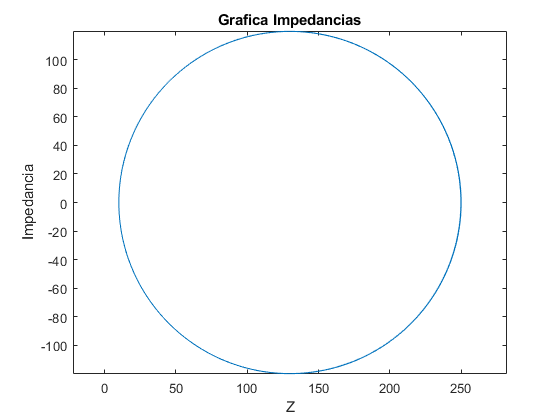

% Impedancia
Zz = Z0.*((1.+p.*exp(-2*gamma.*z))./(1.-p.*exp(-2*gamma.*z)));
plot(Zz)
title('Grafica Impedancias')
ylabel('Impedancia')
xlabel('Z')
axis equal;

2 - Gráfica de los volajes instantaneos en los puntos de entrada, centro de la línea y carga, podemos ver que en z=0, el voltaje es mucho menor que en la parte de z=l, al igual que con las fecuencias de la señal en z=l/2 tiene una mayor frecuencia que en los otros puntos, y con relacion a la grafica de las magnitudes podemos ver que el voltaje en cada punto de la linea alterna en diferentes  puntos de z. Por lo que su variación es claramente visible en los diferentes puntos de la línea.

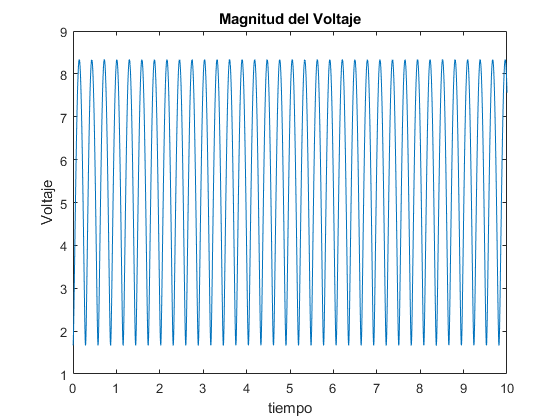

% Magnitud Voltaje
voltaje = A .*abs((1 + p.*exp(-2*gamma.*z)));
figure(1)
plot(z, voltaje)
title('Magnitud del Voltaje')
ylabel('Voltaje')
xlabel('tiempo')

Y La grafica de los valores instantaneos :

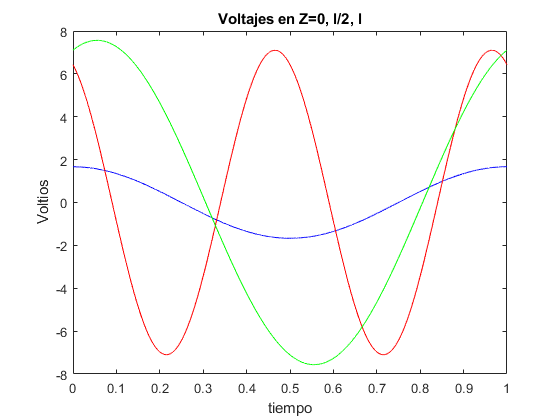

% Voltaje instantaneo
z = 0;
v = A .*(1 + p.*exp(-2*gamma.*z));
t = linspace(1,2*T,10000);
Vt1 = real(v.*exp(1i*w.*t)); %Voltaje instantaneo
plot(t,Vt1,'b');
title('Voltajes en Z={0, l/2, l}')
ylabel('Voltaje')
xlabel('tiempo')

z = long/2;
v = A .*(1 + p.*exp(-2*gamma.*z));
t = linspace(1,T,10000);
Vt2 = real(v.*exp(1i*w.*t)); %Voltaje instantaneo
hold on
plot(t,Vt2,'r');
title('Voltajes en Z={0, l/2, l}')
ylabel('Voltaje')
xlabel('tiempo')

z = long;
v = A .*(1 + p.*exp(-2*gamma.*z));
t = linspace(1,2*T,10000);
Vt3 = real(v.*exp(1i*w.*t)); %Voltaje instantaneo
hold on
plot(t,Vt3,'g');
title('Voltajes en Z={0, l/2, l}')
ylabel('Voltios')
xlabel('tiempo')

3 - Grafique las corrientes instantaneas en cada en los puntos de entrada, centro de la linea y carga, al igual que con el voltaje la coriiente tiene un comportamiento que en z=0 su valor en bajo mientras que en otras partes de la linea la corriente crece, y con relación a la gráfica de las magnitudes podemos ver que la señal tiene un punto de corte donde la corriente sube creando una especie de onda senoidal con solo parte positiva. 

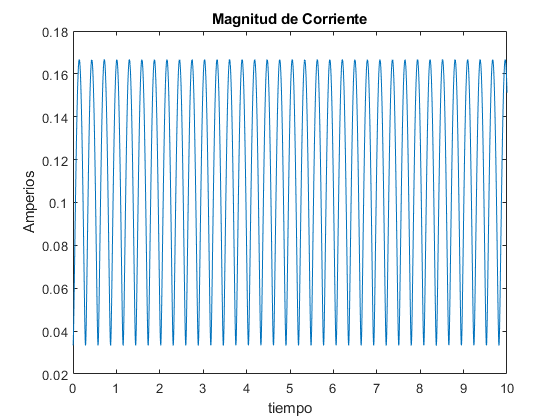

% Magnitud Corriente
z=linspace(0,long,10000);
v = A .*abs((1 + p.*exp(-2*gamma.*z)));
corriente = v./Z0;
figure(2)
plot(z, corriente)
title('Magnitud de Corriente')
ylabel('Amperios')
xlabel('tiempo')

Y para la corriente instantanea :

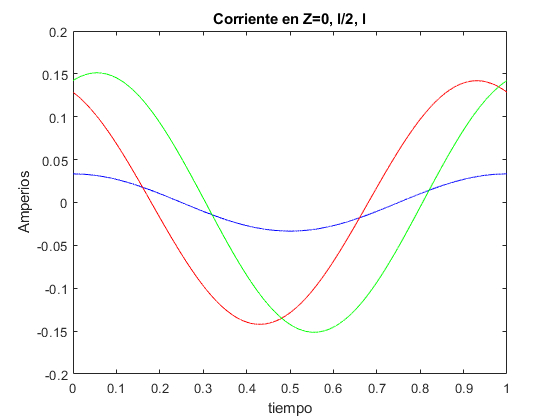

% Corriente instantaneo
z = 0;
v = A .*(1 + p.*exp(-2*gamma.*z));
i = v./Z0;
t = linspace(1,2*T,10000);
It1 = real(i.*exp(1i*w.*t)); %Voltaje instantaneo
figure(5)
plot(t,It1, 'b');
title('Corriente en Z={0, l/2, l}')
ylabel('Amperios')
xlabel('tiempo')

z = 5;
v = A .*(1 + p.*exp(-2*gamma.*z));
i = v./Z0;
t = linspace(1,2*T,10000);
It2 = real(i.*exp(1i*w.*t)); %Voltaje instantaneo
hold on
plot(t,It2, 'r');

z = 10;
v = A .*(1 + p.*exp(-2*gamma.*z));
i = v./Z0;
t = linspace(1,2*T,10000);
It3 = real(i.*exp(1i*w.*t)); %Voltaje instantaneo
hold on
plot(t,It3, 'g');

4 - Grafique la impedancia de la linea como el cociente entre la magnitud del voltaje y la magnitud de la corriente, podemos ver que es las impedancias dan un valor mas pequeño pero forman la misma figura, a pesar de la similitud, estas se diferencian en los valores obtenidos, pues esta gráfica presenta valores más pequeños.

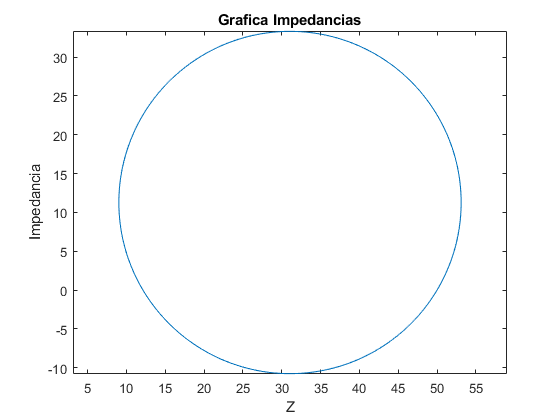

z=linspace(0,long,10000);
vc = A .*(1 + p.*exp(-2*gamma.*z));
ic = v./Z0;
Zr= vc./ic;
figure()
plot(Zr)
axis equal
title('Grafica Impedancias')
ylabel('Impedancia')
xlabel('Z')

5 - Gráfica de la impedancia en cualquier punto de la linea, con alfa diferente de cero, como se puede ver en la gráfica, la línea al tener una atenuación vemos que la carga va disminuye en forma de espiral.

% Calculo de valores necesarios para funciones
alfa = 0.5

alfa = 0.5000

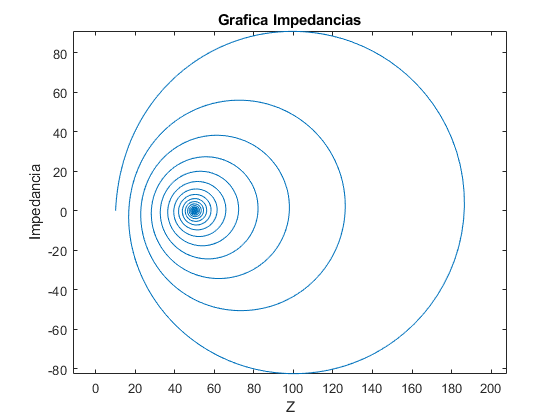

lambda=c/(sqrt(er)*f);
b=2*pi/lambda;
gamma=alfa+1i*b;
w=2*pi*f;
T=1/f;
p = (Zl-Z0)/(Zl+Z0);
z=linspace(0,long,10000);
% Impedancia
Zz = Z0.*((1.+p.*exp(-2*gamma.*z))./(1.-p.*exp(-2*gamma.*z)));
figure()
plot(Zz)
axis equal
title('Grafica Impedancias')
ylabel('Impedancia')
xlabel('Z')

6 - La magnitud del voltaje va disminuye de forma exponencial tanto en la parte positiva y negativa de la senoidal hasta llegar a un valor constante de A, y los voltajes instantaneos vemos que tanto z=l/2 y z=l la honda tiene una amplitud de 5 voltios mientras que la de z=0 vemos que su voltaje es menor ya que en la grafica de la magnitud de voltaje en z=0 es aproximadamente 1,6 voltios.

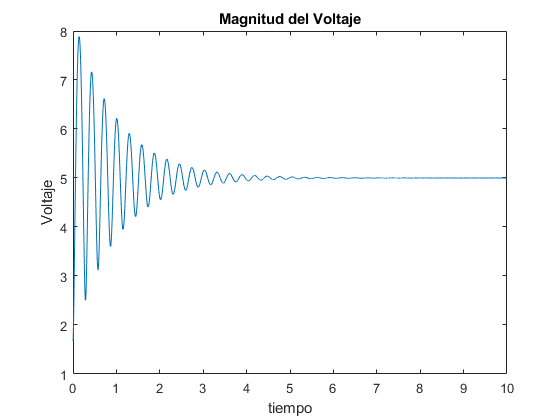

% Magnitud Voltaje
voltaje = A .*abs((1 + p.*exp(-2*gamma.*z)));
figure()
plot(z, voltaje)
title('Magnitud del Voltaje')
ylabel('Voltaje')
xlabel('tiempo')

Y La grafica de los valores instantaneos :

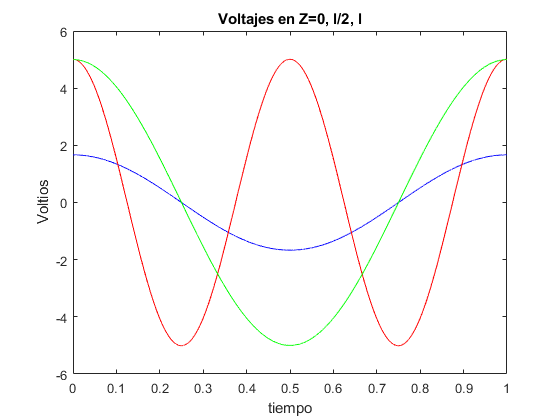

% Voltaje instantaneo
z = 0;
v = A .*(1 + p.*exp(-2*gamma.*z));
t = linspace(1,2*T,10000);
Vt1 = real(v.*exp(1i*w.*t)); %Voltaje instantaneo
plot(t,Vt1,'b');
title('Voltajes en Z={0, l/2, l}')
ylabel('Voltaje')
xlabel('tiempo')

z = long/2;
v = A .*(1 + p.*exp(-2*gamma.*z));
t = linspace(1,T,10000);
Vt2 = real(v.*exp(1i*w.*t)); %Voltaje instantaneo
hold on
plot(t,Vt2,'r');
title('Voltajes en Z={0, l/2, l}')
ylabel('Voltaje')
xlabel('tiempo')

z = long;
v = A .*(1 + p.*exp(-2*gamma.*z));
t = linspace(1,2*T,10000);
Vt3 = real(v.*exp(1i*w.*t)); %Voltaje instantaneo
hold on
plot(t,Vt3,'g');
title('Voltajes en Z={0, l/2, l}')
ylabel('Voltios')
xlabel('tiempo')

7 - En la magnitud corriente pasa lo mismo que con el voltaje tiene una tendencia a decrecer de forma exponencial en parte positiva como negativa hasta llegar a una constante que en este caso es 0,1 amperios y con respecto a las corrientes instantaneas vemos como las corrientes en z=l/2 y z=l la corriente es exactamente igual (acercar la imagen si no se nota), mientras que la corriente en z=0 es menor conrespondiendo al valor referente a la gráfica de la magnitud en ese punto.

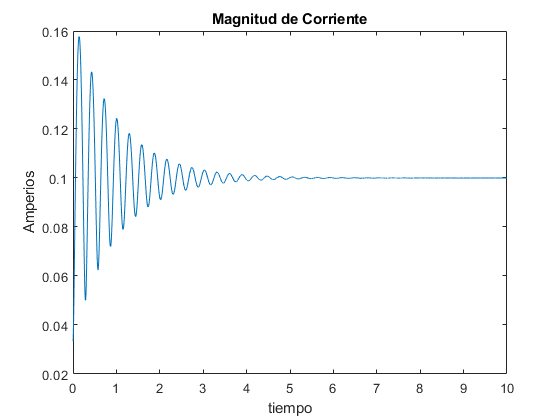

% Magnitud Corriente
z=linspace(0,long,10000);
v = A .*abs((1 + p.*exp(-2*gamma.*z)));
corriente = v./Z0;
figure()
plot(z, corriente)
title('Magnitud de Corriente')
ylabel('Amperios')
xlabel('tiempo')

Y para las corrientes instantaneas su gráfica es 

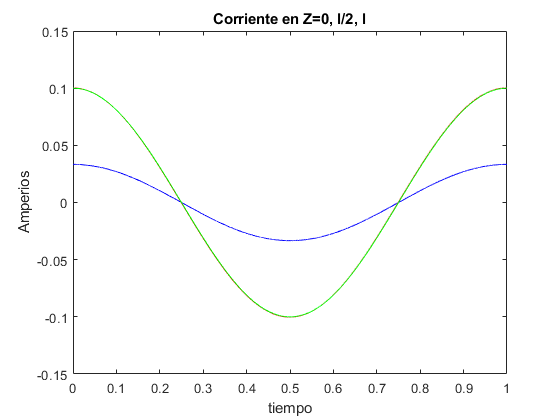

% Corriente instantaneo
z = 0;
v = A .*(1 + p.*exp(-2*gamma.*z));
i = v./Z0;
t = linspace(1,2*T,10000);
It1 = real(i.*exp(1i*w.*t)); %Voltaje instantaneo
figure()
plot(t,It1, 'b');
title('Corriente en Z={0, l/2, l}')
ylabel('Amperios')
xlabel('tiempo')

z = 5;
v = A .*(1 + p.*exp(-2*gamma.*z));
i = v./Z0;
t = linspace(1,2*T,10000);
It2 = real(i.*exp(1i*w.*t)); %Voltaje instantaneo
hold on
plot(t,It2, 'r');

z = 10;
v = A .*(1 + p.*exp(-2*gamma.*z));
i = v./Z0;
t = linspace(1,2*T,10000);
It3 = real(i.*exp(1i*w.*t)); %Voltaje instantaneo
hold on
plot(t,It3, 'g');

8 - La gráfica de las impedancias con respecto a su forma de como el cociente entre la magnitud del voltaje y la magnitud de la corriente, podemos observar que por el cambio de los números cambia un poco el centro de la impedancia pero si la analizamos un poco mejor podemos ver que la impedancia disminuye en forma de espiral como la primera figura que se realizo en el punto 5, sin embargo al compararlas, se encuentra que esta gráfica tiene valores menores.

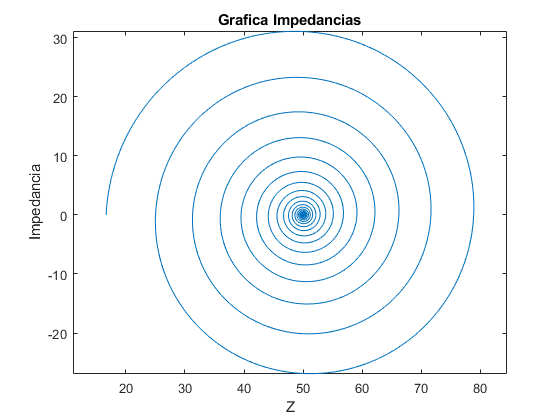

z=linspace(0,long,10000);
vc = A .*(1 + p.*exp(-2*gamma.*z));
ic = v./Z0;
Zr= vc./ic;
figure()
plot(Zr)
axis equal
title('Grafica Impedancias')
ylabel('Impedancia')
xlabel('Z')